%Creating a low pass filter
n = -100:100

n =   -100   -99   -98   -97   -96   -95   -94   -93   -92   -91   -90   -89   -88   -87   -86   -85   -84   -83   -82   -81   -80   -79   -78   -77   -76   -75   -74   -73   -72   -71   -70   -69   -68   -67   -66   -65   -64   -63   -62   -61   -60   -59   -58   -57   -56   -55   -54   -53   -52   -51


b = zeros(1,length(n))

b =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


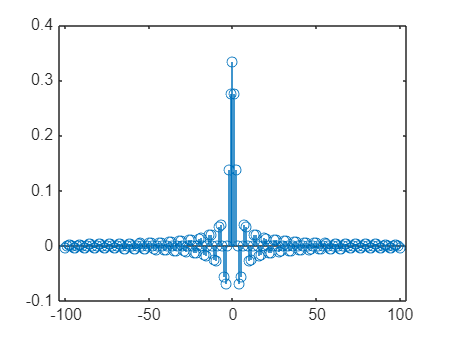

for i = 1:length(n)
    if (n(i) == 0)
        b(i) = 1/3;
    else
        b(i) = sin(pi* n(i) / 3)/(pi* n(i));
    end 
end

figure;
stem(n,b);

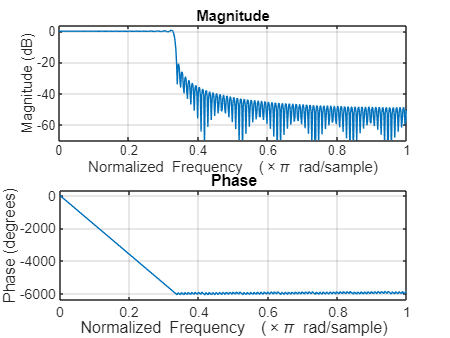


figure;
freqz(b);

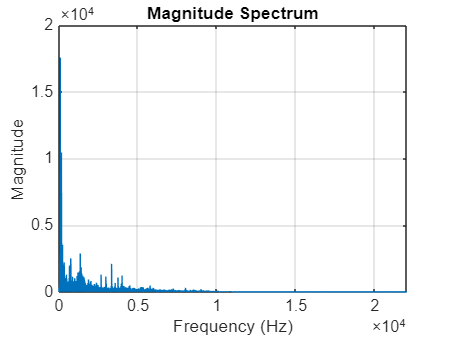

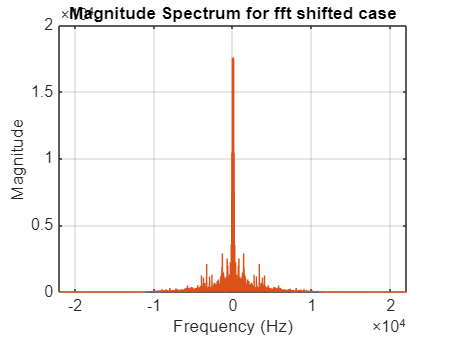

%Taking a real time audio and plotting it
[audio_sig, fs] = audioread("music_new.mp3");
audio_fft = fft(audio_sig(:,1));
myFFtFunction(audio_sig, fs, true, true);

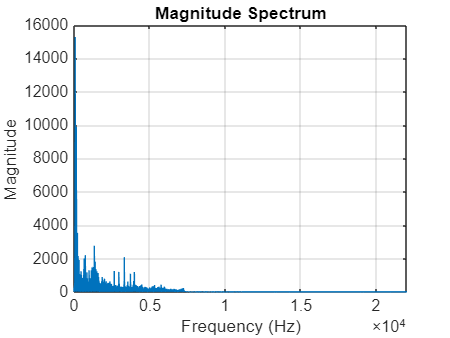

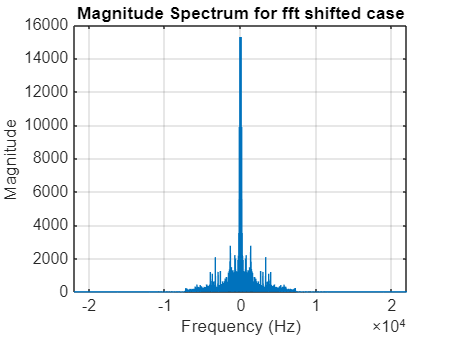

%Filtering the audio and plotting the filtered audio
filtered_y = conv(audio_sig(:,1),b);
filtered_y1 = conv(audio_sig(:,2),b);

filterY = [filtered_y, filtered_y1];

filtered_audio_fft = fft(filtered_y);
myFFtFunction(filtered_y, fs, true, true);